# BarTrace

Application to track the path and speed of a barbell when weightlifting. 

Started by Dave Bergstein (dbergstein@gmail.com)

I'm learning to weightlift and find it helpful to see the path and speed of the barbell of my lifts. I also enjoy playing with deep learning. I train at Grit City in the Bronx, NYC (@concretejunglegritsc on Instagram). Randy Triunfel (@thebarbellmasochist on Instagram) is a competitive weightlifter and my coach. Randy is a great lifter and I learn a lot from seeing his lifts as well.

Pull Requests are welcomed. And feel free to fork and use consistent with the MIT license. I didn't include all the video data here given it's size. The video data was all taken at the gym with either Randy or me, so the model wasn't trained with much variety.

## Project Organization

- application: production code including production model

- data: raw data, see readme files for credit & permission

- models: image processing and trained models

- training: code for training models

- exploring: area to play around

- tests: unit, performance, and application tests (to be written)

## Open Issues

- Add name-value pairs to tracePlate method

- Add tests and check tests

## Getting Started

Import video

vid = liftVid("DaveShort.mp4");

Find plate in each frame and draw in circle

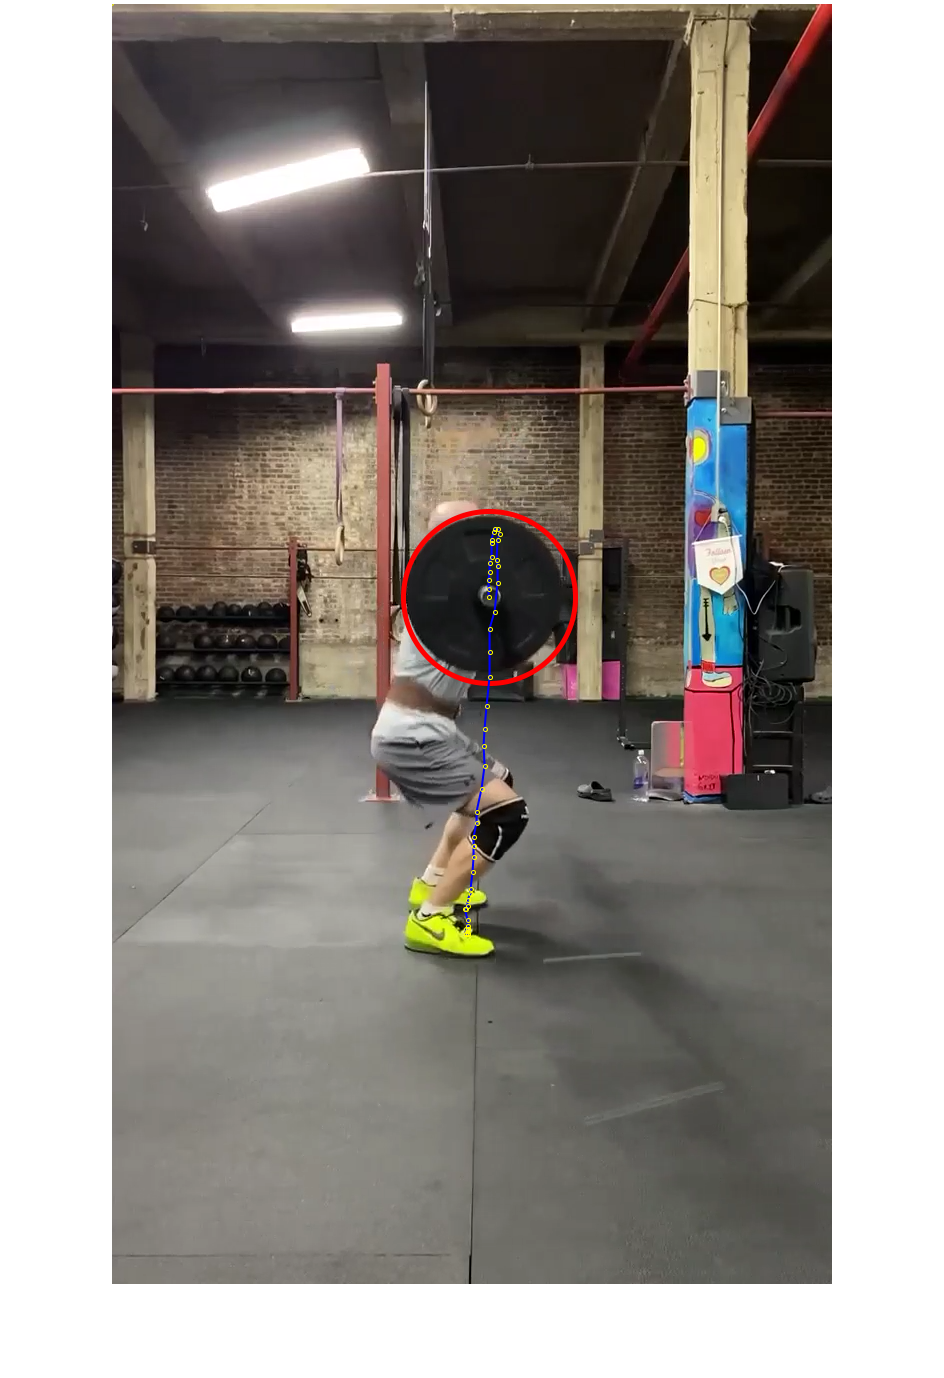

for n = 1:54
    frame = vid.processNextFrame;
end
imshow(frame)

Show all frames

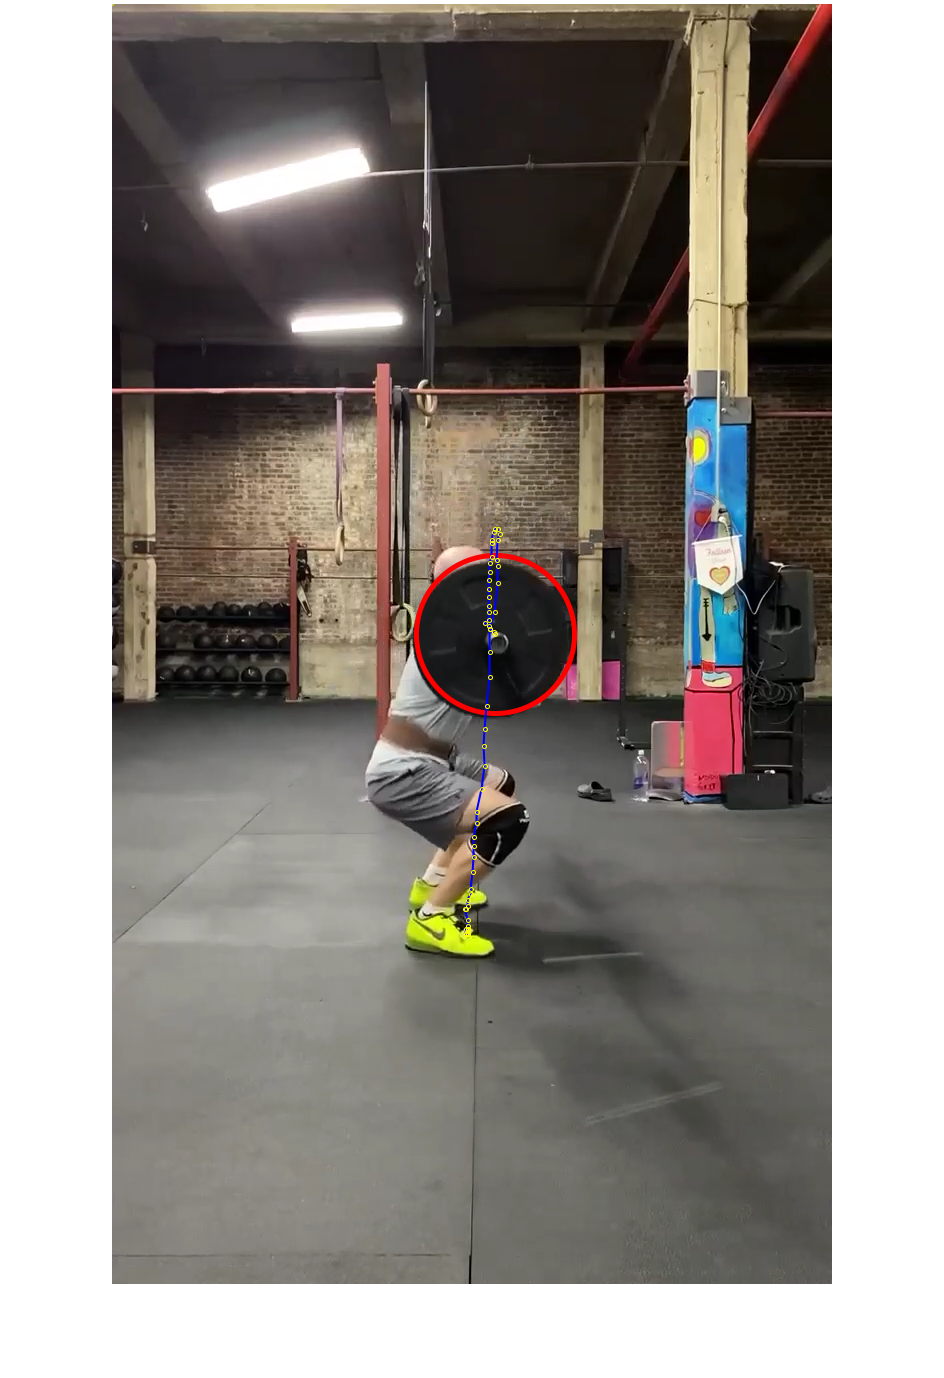

vid = liftVid("DaveShort.mp4");
vid.tracePlate(true,false,"Result1")

Save annotated video

vid = liftVid("DaveShort.mp4");
vid.tracePlate(true,true,"Result1")

## Analyze the second pull

edit("Analyze2ndPull.mlx")

## Details

liftVid finds the barbell plate in each frame and traces it's path. Yellow markers at each frame help gauge barbell speed. Videos were all shot on an iPhone 11 at 30 fps. The model was only trained with black plates on a red and black background.

I used two approaches to find the plate in each frame:

- Image processing based on imfindcircles

- Deep learning based on a pre-trained CNN network with a YOLO network on the back end trained here

Image processing (approach #1) was first used to label images. The image processing took long and wasn't always accurate, especially when the black plates were against a black background. The labeling was adjusted and improved using the Video Labeling App. Training data with different lifters was used to train the model.